%% ============================================================
%  Estimacion de friccion en pendulo invertido con helice
%  Archivo: Experimentos.xlsx
%  Hoja: "Experimentos fricción"
%
%  Columna A: tiempo, pero se reconstruye porque algunas celdas
%             fueron convertidas por Excel a fechas.
%  Columnas B:K: angulos de los 10 experimentos
%
%  Modelo:
%  |theta - theta_eq| = A*exp(-sigma*t)
%
%  Friccion viscosa:
%  b = 2*J*sigma
%% ============================================================

clear; clc; close all;

%% ---------------- CONFIGURACION ----------------
archivo = "Experimentos.xlsx";
hoja = "Experimentos fricción";

Ts = 0.01;                         % 10 ms = 0.01 s
nExperimentosEsperados = 10;

% En tu Excel los angulos parecen estar en miligrados:
% 91496 = 91.496 grados
escalaAngulo = 1e-3;               % pasar de miligrados a grados

% Inercia total del pendulo respecto al eje
m_barra = 0.08;                    % kg
L_barra = 0.195;                   % m
m_helice_motor = 0.05;             % kg
L_cm_helice = 0.04;                % m

J = (1/3)*m_barra*L_barra^2 + m_helice_motor*L_cm_helice^2;

fprintf("Inercia usada: J = %.6e kg*m^2\n", J);

Inercia usada: J = 1.094000e-03 kg*m^2


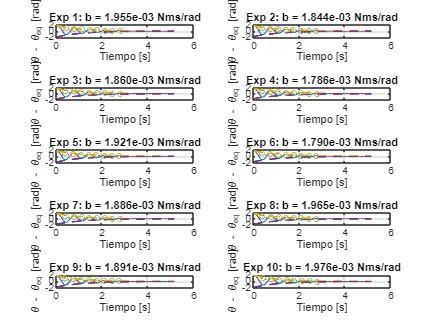


% Parametros para detectar picos
minDist_s = 0.15;                  % distancia minima entre picos [s]
porcentajeMinimo = 0.05;           % ignora picos menores al 5% del maximo

%% ---------------- IMPORTAR DATOS ----------------
C = readcell(archivo, "Sheet", hoja);

% Quitar filas y columnas completamente vacias
esVacio = cellfun(@(x) isempty(x) || ...
    (isnumeric(x) && isscalar(x) && isnan(x)), C);

C = C(~all(esVacio,2), :);
C = C(:, ~all(esVacio,1));

% Los datos empiezan en la fila 2 porque la fila 1 son encabezados
theta_raw = C(2:end, 2:11);

% Convertir celdas a matriz numerica
theta = cellfun(@convertirANumero, theta_raw);

% Quitar filas sin datos de angulo
filasValidas = any(isfinite(theta), 2);
theta = theta(filasValidas, :);

% Tomar maximo 10 experimentos
nExp = min(nExperimentosEsperados, size(theta,2));
theta = theta(:,1:nExp);

% Reconstruir tiempo en segundos
% No se usa la columna A porque algunas celdas fueron convertidas a fechas.
N = size(theta,1);
t = (1:N)'*Ts;

% Convertir angulos: miligrados -> grados -> radianes
theta_deg = theta * escalaAngulo;
theta_rad = deg2rad(theta_deg);

%% ---------------- PROCESAMIENTO ----------------
sigma = nan(nExp,1);
b_sobre_J = nan(nExp,1);
b = nan(nExp,1);
A = nan(nExp,1);
R2 = nan(nExp,1);
theta_eq = nan(nExp,1);
numPicos = nan(nExp,1);

figure("Name","Ajuste de envolvente - Pendulo con helice");
tiledlayout(5,2);

for k = 1:nExp

    th = theta_rad(:,k);

    % Rellenar datos faltantes
    th = fillmissing(th, "linear", "EndValues", "nearest");

    % Estimar equilibrio como el promedio final
    nFinal = max(10, round(0.15*length(th)));
    theta_eq(k) = mean(th(end-nFinal+1:end), "omitnan");

    % Centrar la señal respecto al equilibrio
    th_c = th - theta_eq(k);

    % Suavizado para reducir ruido
    ventanaMediana = max(3, round(0.03/Ts));
    ventanaMedia   = max(3, round(0.04/Ts));

    th_f = smoothdata(th_c, "movmedian", ventanaMediana);
    th_f = smoothdata(th_f, "movmean", ventanaMedia);

    % Envolvente medida usando valor absoluto
    env_medida = abs(th_f);

    % Umbral para evitar ajustar ruido final
    maxEnv = max(env_medida);
    ruidoFinal = std(env_medida(end-nFinal+1:end), "omitnan");
    umbral = max([porcentajeMinimo*maxEnv, 4*ruidoFinal, eps]);

    % Detectar picos de la envolvente
    [pks, locs] = findpeaks(env_medida, t, ...
        "MinPeakDistance", minDist_s, ...
        "MinPeakProminence", umbral/2);

    % Filtrar picos pequenos
    idx = pks > umbral;
    pksFit = pks(idx);
    tFit = locs(idx);

    % Ajuste exponencial
    if numel(pksFit) >= 4

        % ln(env) = ln(A) - sigma*t
        coef = polyfit(tFit, log(pksFit), 1);

        sigma(k) = -coef(1);
        A(k) = exp(coef(2));

        % b/J = 2*sigma
        b_sobre_J(k) = 2*sigma(k);

        % b = 2*J*sigma
        b(k) = 2*J*sigma(k);

        % Calidad del ajuste
        y = log(pksFit);
        yfit = polyval(coef, tFit);
        R2(k) = 1 - sum((y - yfit).^2)/sum((y - mean(y)).^2);

        numPicos(k) = numel(pksFit);

        env_fit = A(k)*exp(-sigma(k)*t);

    else
        env_fit = nan(size(t));
    end

    %% Grafica individual
    nexttile;
    plot(t, th_c, "LineWidth", 1); hold on; grid on;
    plot(t, env_medida, ":", "LineWidth", 1);

    if ~isnan(sigma(k))
        plot(t, env_fit, "--", "LineWidth", 1.5);
        plot(t, -env_fit, "--", "LineWidth", 1.5);
        plot(tFit, pksFit, "o", "MarkerSize", 4);

        title(sprintf("Exp %d: b = %.3e Nms/rad", k, b(k)));
    else
        title(sprintf("Exp %d: ajuste no valido", k));
    end

    xlabel("Tiempo [s]");
    ylabel("\theta - \theta_{eq} [rad]");
end


%% ---------------- RESULTADOS ----------------
experimento = (1:nExp).';

% Forzar que todas las variables sean vectores columna
theta_eq  = theta_eq(:);
sigma     = sigma(:);
b_sobre_J = b_sobre_J(:);
b         = b(:);
A         = A(:);
R2        = R2(:);
numPicos  = numPicos(:);

% Crear tabla
resultados = table(experimento, theta_eq, sigma, b_sobre_J, b, A, R2, numPicos, ...
    'VariableNames', {'Exp', 'theta_eq_rad', 'sigma_1_s', 'b_sobre_J_1_s', ...
                      'b_Nms_rad', 'A_rad', 'R2', 'numPicos'});

disp(resultados);

    Exp    theta_eq_rad    sigma_1_s    b_sobre_J_1_s    b_Nms_rad    A_rad       R2       numPicos
    ___    ____________    _________    _____________    _________    ______    _______    ________

     1       0.0090957      0.89355        1.7871        0.0019551    1.8529    0.98067       8    
     2       -0.017393      0.84274        1.6855        0.0018439    1.6914    0.98361       8    
     3       0.0067819      0.85022        1.7004        0.0018603    1.7593    0.98294       8    
     4       0.0071808       0.8161        1.6322        0.0017856    1.6775    0.98474       8    
     5       0.0051063      0.87785        1.7557        0.0019207    1.7914     0.9787       8    
     6       0.0061436     


fprintf("\n=====================================\n");

fprintf("Resultados promedio:\n");

Resultados promedio:


fprintf("sigma promedio = %.6f 1/s\n", mean(sigma, "omitnan"));

sigma promedio = 0.862617 1/s


fprintf("b/J promedio   = %.6f 1/s\n", mean(b_sobre_J, "omitnan"));

b/J promedio   = 1.725235 1/s


fprintf("b promedio     = %.6e N*m*s/rad\n", mean(b, "omitnan"));

b promedio     = 1.887407e-03 N*m*s/rad


fprintf("b desv. est.   = %.6e N*m*s/rad\n", std(b, "omitnan"));

b desv. est.   = 6.828873e-05 N*m*s/rad


fprintf("=====================================\n");

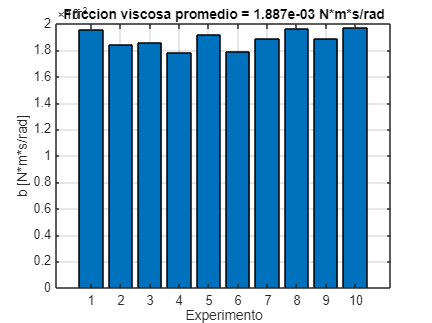


writetable(resultados, "resultados_friccion_pendulo.xlsx");

%% ---------------- GRAFICA FINAL ----------------
figure("Name","Friccion estimada por experimento");

bar(experimento, b);
grid on;
xlabel("Experimento");
ylabel("b [N*m*s/rad]");
title(sprintf("Friccion viscosa promedio = %.3e N*m*s/rad", mean(b, "omitnan")));


%% ---------------- FUNCION AUXILIAR ----------------
function x = convertirANumero(celda)

    if isnumeric(celda)
        x = celda;
    elseif isstring(celda) || ischar(celda)
        x = str2double(string(celda));
    else
        x = NaN;
    end

end